# Structure From Motion of Medusa Head Sequence

## Read the Input Image Sequence

Read and display the image sequence.

videoReader = mmread('medusa.dv');
imds=videoReader.frames;

% Display the images.
figure
% Convert the images to grayscale.
images = cell(1, length(imds));
for i = 1:size(imds,2)
    I = imds(i).cdata;
    images{i} = im2gray(I);
end
imshow([images{1},images{50};images{100},images{150};images{200},images{250};images{300},images{350}])

title('Input Image Sequence');

## Load Camera Parameters

Load the `cameraParameters` object created using the  [Camera Calibrator app](docid:vision_ref#burd_hd-1).

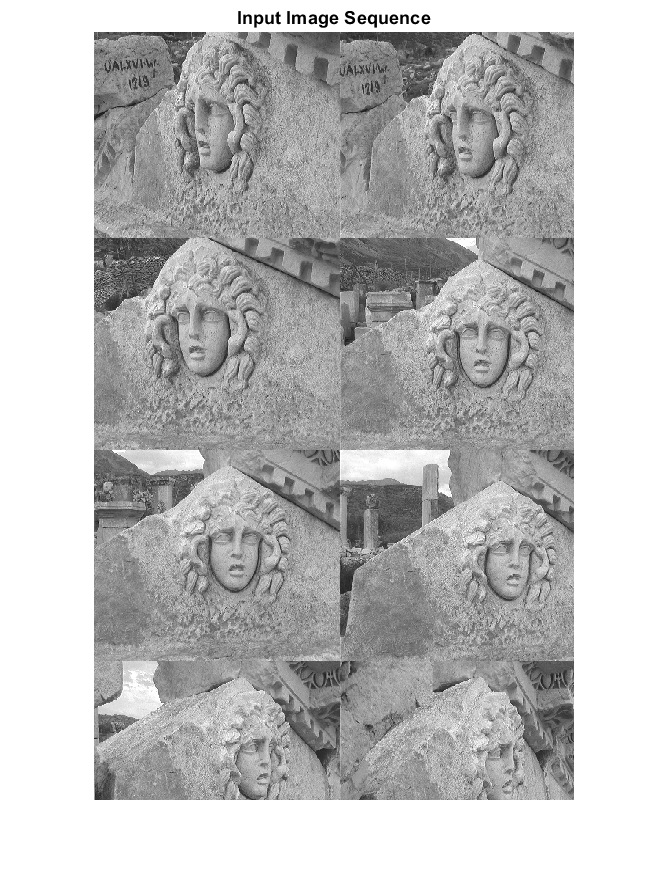

% Get intrinsic parameters of the camera
% intrinsics = cameraParams.Intrinsics;
focalLength    = [615 615];        % specified in units of pixels
principalPoint = [576/2 720/2];        % in pixels [x, y]

imageSize      = size(I,[1,2]); % in pixels [mrows, ncols]
intrinsics = cameraIntrinsics(focalLength, principalPoint, imageSize);

## Create a View Set Containing the First View

Use an [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) object to store and manage the image points and the camera pose associated with each view, as well as point matches between pairs of views. Once you populate an [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) object, you can use it to find point tracks across multiple views and retrieve the camera poses to be used by [`triangulateMultiview`](docid:vision_ref#bu4s48j-1) and [`bundleAdjustment`](docid:vision_ref#bu48f97-1) functions.

I = images{1};

% Detect features. Increasing 'NumOctaves' helps detect large-scale
% features in high-resolution images. Use an ROI to eliminate spurious
% features around the edges of the image.
roi = [200, 100, size(I, 2)- 2*200, size(I, 1)- 2*100];
prevPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);

% Extract features. 
[prevFeatures,valid_points] = extractFeatures(I, prevPoints);
figure; imshow(I); hold on;
plot(valid_points.selectStrongest(100),'showOrientation',true);
% Create an empty imageviewset object to manage the data associated with each
% view.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
viewId = 1;
vSet = addView(vSet, viewId, rigid3d, 'Points', prevPoints);

## Add the Rest of the Views

Go through the rest of the images. For each image

- Match points between the previous and the current image.

- Estimate the camera pose of the current view relative to the previous view.

- Compute the camera pose of the current view in the global coordinate system relative to the first view.

- Triangulate the initial 3-D world points.

- Use bundle adjustment to refine all camera poses and the 3-D world points.

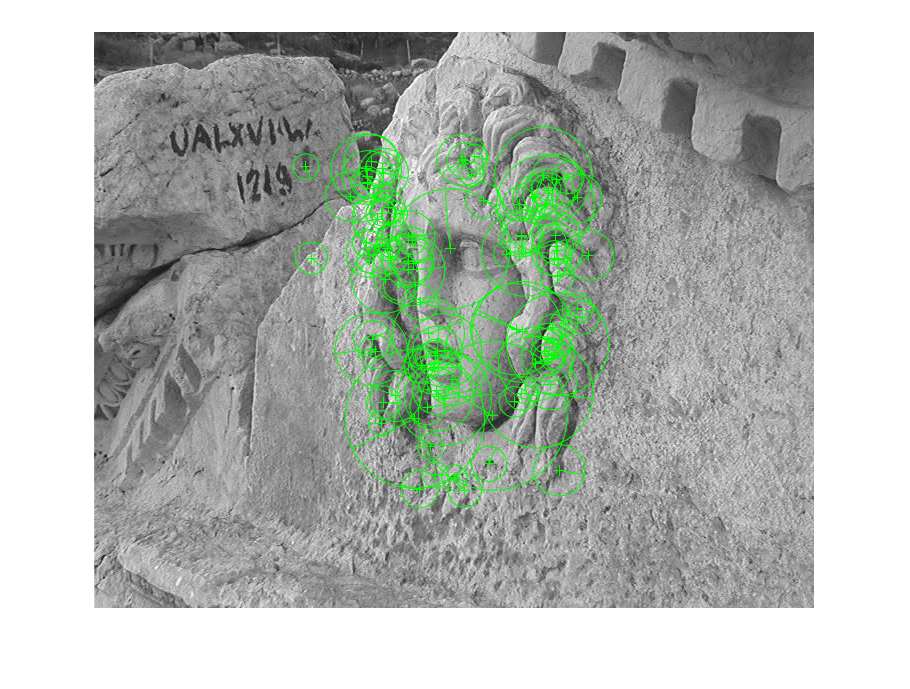

for i = 2:numel(images)
% for i = 2:40

    disp(string(i))
    I = images{i};
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);


    currFeatures = extractFeatures(I, currPoints);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        'MaxRatio', .5, 'Unique',  true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
%     figure(i); 
%     showMatchedFeatures(images{i-1},I,matchedPoints1,matchedPoints2);

    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relativeOrient, relativeLoc, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    
    % Get the table containing the previous camera pose.
    prevPose = poses(vSet, i-1).AbsolutePose;
    relPose  = rigid3d(relativeOrient(:,:,1), relativeLoc(1,:));
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigid3d(relPose.T * prevPose.T);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, 'Points', currPoints);

    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, i-1, i, relPose, 'Matches', indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-D world points and camera poses.
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
        tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
        'PointsUndistorted', true);

    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end

2
3
4
5
6
7
8
9
10
11
12
13
14
15
16
17
18
19
20
21
22
23
24
25
26
27
28
29
30
31
32
33
34
35
36
37
38
39
40
41
42
43
44
45
46
47
48
49
50
51
52
53
54
55
56
57
58
59
60
61
62
63
64
65
66
67
68
69
70
71
72
73
74
75
76
77
78
79
80
81
82
83
84
85
86
87
88
89
90
91
92
93
94
95
96
97
98
99
100
101
102
103
104
105
106
107
108
109
110
111
112
113
114
115
116
117
118
119
120
121
122
123
124
125
126
127
128
129
130
131
132
133
134
135
136
137
138
139
140
141
142
143
144
145
146
147
148
149
150
151
152
153
154
155
156
157
158
159
160
161
162
163
164
165
166
167
168
169
170
171
172
173
174
175
176
177
178
179
180
181
182
183
184
185
186
187
188
189
190
191
192
193
194
195
196
197
198
199
200
201
202
203
204
205
206
207
208
209
210
211
212
213
214
215
216
217
218
219
220
221
222
223
224
225
226
227
228
229
230
231
232
233
234
235
236
237
238
239
240
241
242
243
244
245
246
247
248
249
250
251
252
253
254
255
256
257
258
259
260
261
262
263
264
265
266
267
268
269
270
271
272
273
274
275
276
277
27

Error using estimateEssentialMatrix>checkRuntimeStatus (line 184)
matchedPoints1 and matchedPoints2 do not have enough points. The number of points in each set must be at least 5.

Error in estimateEssentialMatrix (line 176)
    checkRuntimeStatus(statusCode, status)

Error in 

## Display Camera Poses

Display the refined camera poses and 3-D world points.

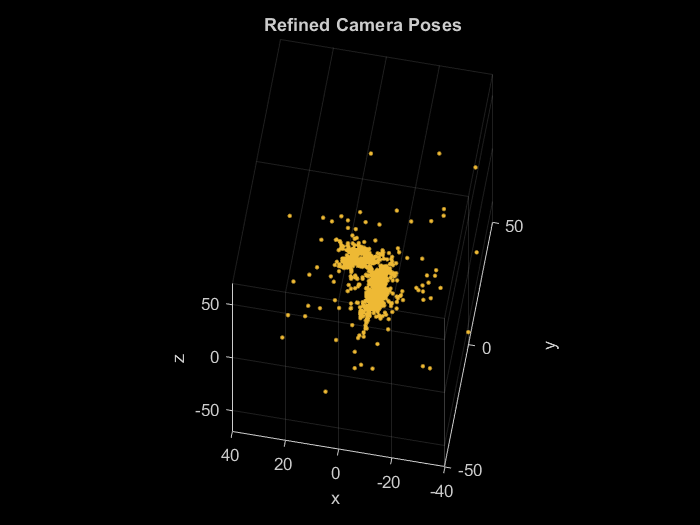

% Display camera poses.
camPoses = poses(vSet);
% clf
figure;
% plotCamera(camPoses, 'Size', 0.01);
% hold on

% Exclude noisy 3-D points.
goodIdx = (reprojectionErrors < 0.5);
xyzPoints_good = xyzPoints(goodIdx, :);

% Display the 3-D points.
pcshow(xyzPoints_good, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-40, loc1(1)+40]);
ylim([loc1(2)-50, loc1(2)+50]);
zlim([loc1(3)-70, loc1(3)+70]);
camorbit(0, -30);
xlabel('x')
ylabel('y')
zlabel('z')
title('Refined Camera Poses');

## Compute Dense Reconstruction

Go through the images again. This time detect a dense set of corners, and track them across all views using[` vision.PointTracker`](docid:vision_ref#btghk3u-1).

% Read and undistort the first image
I = undistortImage(images{1}, intrinsics); 

% Detect corners in the first image.
roi = [200, 100, size(I, 2)- 2*200, size(I, 1)- 2*100];
prevPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);

% Create the point tracker object to track the points across views.
tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 4);

% Initialize the point tracker.
prevPoints = prevPoints.Location;
initialize(tracker, prevPoints, I);

% Store the dense points in the view set.

vSet = updateConnection(vSet, 1, 2, 'Matches', zeros(0, 2));
vSet = updateView(vSet, 1, 'Points', prevPoints);

% Track the points across all views.
for i = 2:numel(images)
% for i = 2:40
    % Read and undistort the current image.
    I = undistortImage(images{i}, intrinsics); 
    
    % Track the points.
    [currPoints, validIdx] = step(tracker, I);
    
    % Clear the old matches between the points.
    if i < numel(images)
        vSet = updateConnection(vSet, i, i+1, 'Matches', zeros(0, 2));
    end
    vSet = updateView(vSet, i, 'Points', currPoints);
    
    % Store the point matches in the view set.
    matches = repmat((1:size(prevPoints, 1))', [1, 2]);
    matches = matches(validIdx, :);        
    vSet = updateConnection(vSet, i-1, i, 'Matches', matches);
end

Error using imageviewset/parseConnectionInputs (line 1265)
ViewId 390 does not exist.

Error in imageviewset/updateConnection (line 597)
            [connTable, unsetColumns] = parseConnectionInputs(this, varargin{:});

% Find point tracks across all views.
tracks = findTracks(vSet);

% Find point tracks across all views.
camPoses = poses(vSet);

% Triangulate initial locations for the 3-D world points.
xyzPoints = triangulateMultiview(tracks, camPoses,...
    intrinsics);

% Refine the 3-D world points and camera poses.
[xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(...
    xyzPoints, tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
    'PointsUndistorted', true);

## Display Dense Reconstruction

Display the camera poses and the dense point cloud.

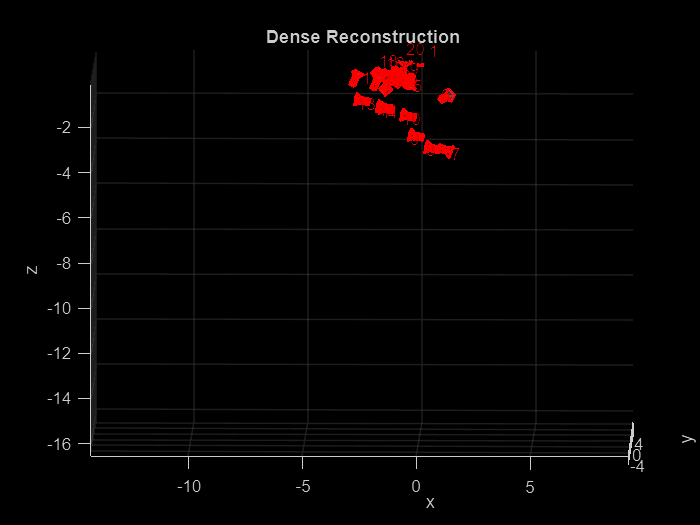

% Display the refined camera poses.
figure;
plotCamera(camPoses(1:20,:), 'Size', 0.2);
hold on

% Exclude noisy 3-D world points.
goodIdx = find(reprojectionErrors < 1);

% Display the dense 3-D world points.
pcshow(xyzPoints, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
% xlim([loc1(1)-8, loc1(1)-6]);
% ylim([loc1(2)-8, loc1(2)-6]);
% zlim([loc1(3)-17, loc1(3)-14]);
xlim([loc1(1)-15, loc1(1)+10]);
ylim([loc1(2)-8, loc1(2)+5]);
zlim([loc1(3)-17, loc1(3)+0]);

camorbit(0, -30);
xlabel('x')
ylabel('y')
zlabel('z')

title('Dense Reconstruction');

## References

Based from [Structure From Motion From Multiple Views - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/vision/ug/structure-from-motion-from-multiple-views.html)

[1] M.I.A. Lourakis and A.A. Argyros (2009). "SBA: A Software Package for Generic Sparse Bundle Adjustment". ACM Transactions on Mathematical Software (ACM) 36 (1): 1-30.

[2] R. Hartley, A. Zisserman, "Multiple View Geometry in Computer Vision," Cambridge University Press, 2003.

[3] B. Triggs; P. McLauchlan; R. Hartley; A. Fitzgibbon (1999). "Bundle Adjustment: A Modern Synthesis". Proceedings of the International Workshop on Vision Algorithms. Springer-Verlag. pp. 298-372.

*Copyright 2015 The MathWorks, Inc.*